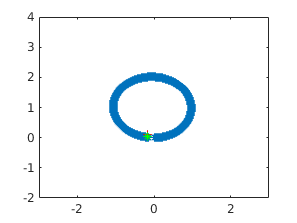

t = 30;
dt = 0.01;
n = t/dt;
radius = 1;
x = zeros(3,n);
u = zeros(2,n);
uu = zeros(2,n);
y = zeros(3,n);
ex = zeros(3,n);
err = zeros(3,n);
% x(1,ts) = x(1,ts-1)+ u(1,ts)/u(2,ts)*(sin(x(3,ts-1)+u(2,ts)*dt)-sin(x(3,ts-1)));
% x(2,ts) = x(1,ts-1)+ u(1,ts)/u(2,ts)*(-cos(x(3,ts-1)+u(2,ts)*dt)+cos(x(3,ts-1)));
% x(3,ts) = x(1,ts-1)+ u(2,ts)*dt;



C = [1 0 0;
     0 1 0;
     0 0 1];

M = [5 0;
     0 3];

Q = [15 0 0;
     0 15 0;
     0 0 15];

P = [1 0 0;
     0 1 0;
     0 0 1];

x(:,1) = [0; 0; 0];
ex(:,1) = [0; 0; 0];
for ts = 2:n
    %% real movement
    uu(1,ts) = 2*pi*radius/t + randn/10;
    uu(2,ts) = 2*pi/t + randn/10;
    
    x(1,ts) = x(1,ts-1)+ uu(1,ts)/uu(2,ts)*(sin(x(3,ts-1)+uu(2,ts)*dt)-sin(x(3,ts-1)));
    x(2,ts) = x(2,ts-1)+ uu(1,ts)/uu(2,ts)*(-cos(x(3,ts-1)+uu(2,ts)*dt)+cos(x(3,ts-1)));
    x(3,ts) = x(3,ts-1)+ uu(2,ts)*dt;

    %% estimated movement
    u(1,ts) = 2*pi*radius/t;
    u(2,ts) = 2*pi/t;

    B = [(sin(ex(3,ts-1)+u(2,ts)*dt)-sin(ex(3,ts-1)))/u(2,ts) -u(1,ts)/(u(2,ts)^2)*(sin(ex(3,ts-1)+u(2,ts)*dt)-sin(ex(3,ts-1)))+u(1,ts)/u(2,ts)*dt*cos(ex(3,ts-1)+u(2,ts)*dt);
     (-cos(ex(3,ts-1)+u(2,ts)*dt)+cos(ex(3,ts-1)))/u(2,ts) -u(1,ts)/(u(2,ts)^2)*(-cos(ex(3,ts-1)+u(2,ts)*dt)+cos(ex(3,ts-1)))+u(1,ts)/u(2,ts)*dt*sin(ex(3,ts-1)+u(2,ts)*dt);
        0   dt];


    A = [1  0   u(1,ts)/u(2,ts)*(cos(ex(3,ts-1)+u(2,ts)*dt)-cos(ex(3,ts-1)));
         0  1   u(1,ts)/u(2,ts)*(sin(ex(3,ts-1)+u(2,ts)*dt)-sin(ex(3,ts-1)));
         0  0   1];
    
    y(1:2,ts) = x(1:2,ts) + randn([2,1])/10;
    y(3,ts) = x(3,ts) + randn/10;
    
%     ex(1,ts) = ex(1,ts-1)+ u(1,ts)/u(2,ts)*(sin(ex(3,ts-1)+u(2,ts)*dt)-sin(ex(3,ts-1)));
%     ex(2,ts) = ex(2,ts-1)+ u(1,ts)/u(2,ts)*(-cos(ex(3,ts-1)+u(2,ts)*dt)+cos(ex(3,ts-1)));
%     ex(3,ts) = ex(3,ts-1)+ u(2,ts)*dt;
    ex(:,ts) = A*ex(:,ts-1) + B*u(:,ts);

    P = A*P*A.' + B*M*B.';
    K = P*C.'/(Q+C*P*C.');
    ex(:,ts) = ex(:,ts) + K*(y(:,ts)-C*ex(:,ts));


    err(:,ts) = norm(x(:,ts)-ex(:,ts));

    plot(x(1,:),x(2,:),'*',ex(1,ts),ex(2,ts),'r+',y(1,ts),y(2,ts),'g*')
    xlim([-3 3]);
    ylim([-2 4]);

    drawnow limitrate
end